# Algorithm 1 - Estimation of linear dynamics with independent data  

Repeat the algorithm 100 times and plot the result in Logarithm

### Initialize parameters and variables

Nrange = [5, 8, 10:10:100]; % number of rollouts
T = 6; % number of timesteps

errorA = zeros(size(Nrange,2),1);
errorB = zeros(size(Nrange,2),1);

l=0;

### With N from 5 to 100

for N = Nrange
    l = l+1;
    
    avgA = 0;
    avgB = 0;
    
    % Average 100 times for each N
    for i = 1:100            
        [deltaA, deltaB] = estimate(N, T);
        avgA = avgA + deltaA;
        avgB = avgB + deltaB;
    end
    
    % Record the average error
    errorA(l) = (avgA/100);
    errorB(l) = (avgB/100);
end

### Plot data

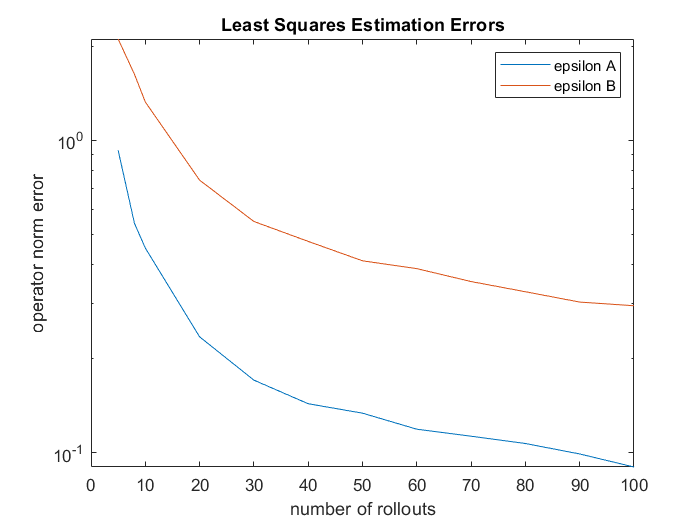

semilogy(Nrange, errorA)
hold on
semilogy(Nrange, errorB)
hold off
title('Least Squares Estimation Errors')
legend('epsilon A', 'epsilon B')
xlabel('number of rollouts')
ylabel('operator norm error')

## Functions

### Generate data and estimate model

function [deltaA, deltaB] = estimate(N, T)

% Initialize variables
    A = [1.01 0.01 0;
         0.01 1.01 0.01;
         0    0.01 1.01];

    B = eye(3);
        
    x = zeros(3, T+1, N); % state
    u = normrnd(0, 1, [3,T,N]);
    w = normrnd(0, 1, [3,T,N]);
    
% Roll out

    for l = 1:N
        x(:,1,l) = 0;  
        
        for t = 1:T
            x(:,t+1,l) = A*x(:,t,l) + B*u(:,t,l) + w(:,t,l);
        end
    end
    
% Denote unknown matrices A, B as vector g of 18 dimensions
% Convert state x and input u to K, h 
% to feed the solver
% Kg = h 

    g = zeros(18, 1); % [a11 a12 a13 a21 ... a33 b11 b12 ... b33] R18
    K = zeros(3, 18, N);
    h = zeros(3, N);
        
    for l = 1:N
        K(1, 1:3, l) = x(:,6,l);
        K(2, 4:6, l) = x(:,6,l);
        K(3, 7:9, l) = x(:,6,l);
        
        K(1, 10:12, l) = u(:,6,l);
        K(2, 13:15, l) = u(:,6,l);
        K(3, 16:18, l) = u(:,6,l);
        
        h(:,l) = x(:,7,l);
        
    end
    
    assignin("base","K",K);
    assignin("base","h",h);
    
% Perform least squares to find g, convert back to A_hat, B_hat

    options = optimoptions(@lsqnonlin,'Display','off');
    g = lsqnonlin(@squares, g, [],[], options);
        
    AB = reshape(g, [3,6])';

    A_hat = AB(1:3,:);
    B_hat = AB(4:6,:);
    
% Return errors
    deltaA = (norm(A_hat-A));
    deltaB = (norm(B_hat-B));
    
end

### Sum of error norm (used for least squares)

function f = squares(m)
    
    N = evalin('base','N');
    K = evalin('base','K');
    h = evalin('base','h');

    f = zeros(N,1);
    
    for l = 1:N
        f(l) = norm(K(:,:,l)*m-h(:,l))^2;
    end
end